# M E 325 Exam 1 Problem 3

The loading spectrum for a machine component is shown below. Assume the part has a cross-sectional area of $0\ldotp 1{\mathrm{in}}^2$. The fatigue strength $S_f$, of the part's material is 100 kpsi at 50,000 stress cycles and 60 kpsi at ${10}^6$ cycles. The ultimate tensile strength, $S_{\mathrm{ut}}$, of the part’s material is 150 kpsi. The single block shown occurs over a time of 5 seconds. Use the Gerber Failure Criterion to determine the value of $\sigma_{e_r }$ .

A = 0.1; % area in^2
S_f_50000 = 100; % kpsi
S_f_1million = 60; % kpsi
S_ut = 150; % kpsi

Determine Basquin Parameters (from sf values)

% Create an augmented matrix for the linearized system of equations for the
% basquin parameters
Aug = [1 log10(50000) log10(S_f_50000); ...
       1 log10(1e6) log10(S_f_1million)]

Aug =     1.0000    4.6990    2.0000
    1.0000    6.0000    1.7782



% convert augmented matrix to reduced row echelon form
reduced = rref(Aug)

reduced =     1.0000         0    2.8013
         0    1.0000   -0.1705



a = 10^reduced(1, 3)

a = 632.7876

b = reduced(2, 3)

b = -0.1705

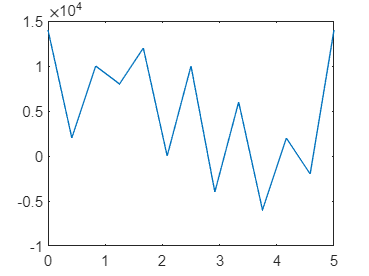



% Plot of loading vs time
x = linspace(0,5,13);
y = [14000, 2000, 10000, 8000, ...
    12000, 0, 10000, -4000, ...
    6000, -6000, 2000, -2000, 14000];

plot(x, y);